## TOPIC 8: Revisiting arrays, pt. 1: useful math and logical arrays

ENGR105, 9/29/20

### Revisiting arrays: useful structures for storing and processing numerical information

We have mostly discussed 1-D (vectors) and 2-D (matrices) arrays, but MATLAB works with N-dimensional arrays. Remember that all of the array concepts we discuss also apply to higher order arrays.

#### Reminder: Vector indexing

Vectors may be indexed using discrete vector indices or single index subscripts.

% Define initial vector 
v = [5 3 4 6 8]

v =      5     3     4     6     8


% Define subsequent vectors through vector indexing
p = v([1 5 4 2])

p =      5     8     6     3


q = v(1:2)

q =      5     3


r = v(end-2:end)

r =      4     6     8


s = v(end:-1:end-3)

s =      8     6     4     3


t = v(1:2:end) 

t =      5     4     8


#### Matrix (and array) indexing

Arrays may be indexed with reference to row, column, page, … etc. subscripts or using single index subscripts.

% Define initial matrix
M = [5 2 4; 3 7 5]

M =      5     2     4
     3     7     5


% Create subsequent matrices through indexing
B = M(1:2,1:2)

B =      5     2
     3     7


C = M(:,1)

C =      5
     3


D = M([1,2],[2,3])

D =      2     4
     7     5


F = M(1,end-1:end)

F =      2     4


G = M(end:-2:1)

G =      5     7     3


#### Adding, subtracting, multiplying and dividing arrays and their elements

We have learned how to perform mathematical operations on vectors and matrices, from element-wise multiplication and addition to matrix multiplication and division.

% Perform array math
B + D     % matrix addition

ans =      7     6
    10    12


B.*D    % element-wise multiplication

ans =     10     8
    21    35


B*M  % matrix multiplication

ans =     31    24    30
    36    55    47


#### Other useful mathematical operations on arrays

**Using arrays with built-in functions**. As was the case with vectors - many built-in MATLAB functions operate on any N-dimensional arrays element by element. For example, if A is a 2x2 matrix, tan(A) will be 2x2 with each element being the tangent of the corresponding element of A. 

A = [pi/4,3*pi/4;5*pi/4,7*pi/4]

A =     0.7854    2.3562
    3.9270    5.4978


% Tangent operation on entire array
tan(A)

ans =     1.0000   -1.0000
    1.0000   -1.0000


The same holds true for most of the common, built-in MATLAB functions (*e.g.* `abs(A)`, `sin(A)`, `log10(A)`)

**Array sums**. Recall that `sum()` of any vector yielded the sum of all elements in that vector.

a = 1:3

a =      1     2     3


sum(a)

ans = 6

N-dimensional arrays may be summed across any of the dimensions or the entire array using the same function. For an N-dimensional array: the sum along the `N`-th dimension may be invoked using `sum(A,N)`, where `N `is the dimension number

- Dimension "1": rows

- Dimension "2": columns

- Dimension "3": pages (and so on)

% Create matrix
A = [1:3;4:6]

A =      1     2     3
     4     5     6


% Sum across each row of A
sum(A,1)

ans =      5     7     9


% Sum across each column of A
sum(A,2)

ans =      6
    15


The **sum of all elements in the array** may be output by nesting `N` number of sum calls (ex. `sum(sum(A))` for a 2D matrix) - the sum starts with the innermost dimension for the most highly-nested sum call.

sum(sum(A))

ans = 21

You may also achieve the previous by unwrapping the matrix to a vector via `sum(A(:))`

sum(A(:))

ans = 21

**Cumulative array sums**. `cumsum``() `sums cumulatively along a *vector* or *some dimension of an array* - unless a dimension is specified, it works on the first non-singleton dimension.

a = 1:4

a =      1     2     3     4


%adds to the next index as it goes through
cumsum(a)

ans =      1     3     6    10


A

A =      1     2     3
     4     5     6


cumsum(A,2)

ans =      1     3     6
     4     9    15


**Array products**. `prod()` calculates the product of array elements using the specified dimension. If no dimension is input, it takes the product along the first non-singleton dimension.

% Vector example
a

a =      1     2     3     4


prod(a)

ans = 24

% Matrix example
A

A =      1     2     3
     4     5     6


prod(A,2)

ans =      6
   120


**Cumulative array products**. `cumprod``()` calculates the cumulative product of array elements along a vector or some dimension of an array - unless a dimension is specified, it works on the first non-singleton dimension.

% Vector example
a

a =      1     2     3     4


cumprod(a)

ans =      1     2     6    24


% Array example
A

A =      1     2     3
     4     5     6


cumprod(A,2)

ans =      1     2     6
     4    20   120


**Note**: many other mathematical functions may be able to operate along rows, columns, or other dimension. Always check the MATLAB `help` documentation to determine how to input the dimension of interest.

#### Useful built-in arrays

MATLAB includes a lot of pre-defined matrices that may be scaled to fit your needs. Generally, there are two ways to specify the dimensions of these matrices:

- A single dimension (`n`) creates an `nxn` square matrix

- Two dimensions (n, m) create a `nxm` matrix

Some pre-defined matrices support `N`-dimensional arrays (ex. `rand(``m,n,p``)`and `randi``(``m,n,p``)`)

% Create an array with all zeros
zeros(3,2)

ans =      0     0
     0     0
     0     0


% Create a matrix with all ones
ones(4)

ans =      1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1


% Create a matrix with equal row, column, and diagonal sums
magic(3)

ans =      8     1     6
     3     5     7
     4     9     2


% Create an identity matrix
eye(3)

ans =      1     0     0
     0     1     0
     0     0     1


% Create a matrix of random integers
randi(4,[2,3])

ans =      2     3     3
     3     4     1


### Logical Arrays

#### Logical numbers

Recall that we can use relational operators compare values and yield a `true` (`1`) or `false` (`0`) numerical result.

#### 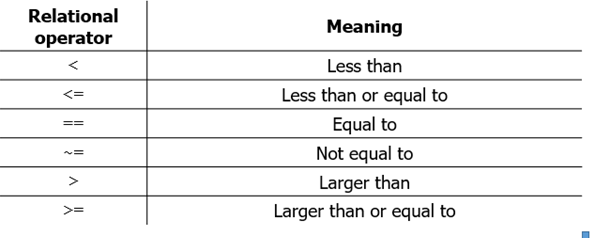

% Relational operator examples
an_1 = 5==2

an_1 = logical
   0


c = 5==2

c = logical
   0


% Relational operators can also operate on variables
dog = 4;
cat = 9;
animal = dog==cat

animal = logical
   0


**Note**: each of these variables is a **scalar of logical *****class***. Each variable and number in MATLAB is of a certain data type. The logical data type specifies that a variable can have one of two possible values: either `1` (`true`) or `0` (`false`).

#### Logical arrays: vectors, matrices, etc. with logical numbers

A logical array is any n-dimensional array that contains only logical type numbers – `logical 0` (`false`) or `logical 1` (`true`). In practice, **logical arrays are most often created by subjecting an array to a relational operator**.

% Define arrays
M = [1,5,8;9,4,3] 

M =      1     5     8
     9     4     3


A = [7,2,6;3,0,5]

A =      7     2     6
     3     0     5


In each of the following examples, **an array is created with the same size as the array subjected to the relational operator**. However, the entries are either `0` or `1`, depending on if the **relational statement is true or false when each corresponding element of the original array is operated on.**

% Creating logical arrays by performing relational operations
V = M == 5

V = 2×3 logical array
   0   1   0
   0   0   0


% Logical matrix based on A, specify which elements are greater than 6
r3 = A > 6

r3 = 2×3 logical array
   1   0   0
   0   0   0


% Create logical matrix indicating which elements in M are greater than the
% corresponding elements in A
out = M>A

out = 2×3 logical array
   0   1   1
   1   1   0


**Note**: as above, the output from each of these is an array of the **logical** class. A logical variable can only take two values: `0` or `1`. We will talk more about data types and classes next week.

A logical array can also be specified by passing an array through the `logical()` command - although this is more rarely used in practical application. In the following, the original vector is converted to a logical vector -- all nonzero elements are converted `logical 1`.

v = [6,4,0,1] 

v =      6     4     0     1


g2 = logical(v)

g2 = 1×4 logical array
   1   1   0   1


### Practice Problem: tic tac toe

**Rules of tic tac toe**:

- The game starts with an empty `3x3` grid.

- Players take turn picking spots (with their marker, usually entering either "x" or "o") in the grid.Thus, there are a possible 9 turns before either one of the players wins or the game ends in a draw.

- If any player gets three spots in a row (horizontal, vertical, or diagonal), she or he wins.

**Goal**: produce a script that "plays" tic tac toe.

**Simpler (initial) goal**: produce a two player version of tic tac toe.

%choose x or o's to be 1 or zeros and then gerate random matrices 
%in order to check how you win you need to check if all indices in a
%row/column/diagonal equal each other 


%step 1: define initial variables
gameboard = zeros(3);
%create array to keep track of positions 
availablePos = 1:9;

%Repeat: alternate between players 
player = 1; %player 1
%checks who's turn it is 
gameStillGoing = 1;
%iterate until someone has one, or game is a draw
availablePos

availablePos =      1     2     3     4     5     6     7     8     9


while gameStillGoing
    %Step 2: make a move, play position
    %populate using single index notation 

    %logical corresponding to valid move
   
    invalidMove = 1;
   
    while invalidMove
        playPos = input("Select a position to play...")
        invalidMove = prod(availablePos ~= playPos) 
    end
    %Update gameboard 
    gameboard(playPos) = player;
    %Step 3: display gameboard
    disp(gameboard)
 
    %Step 4: evaluate stopping condition 
    gameStillGoing = checkEndGame(gameboard, player);
    %step 5 change player
    player = mod(player,2) + 1;
    
end   

playPos = 1

invalidMove = 0

     1     0     0
     0     0     0
     0     0     0



playPos = 2

invalidMove = 0

     1     0     0
     2     0     0
     0     0     0



playPos = 4

invalidMove = 0

     1     1     0
     2     0     0
     0     0     0



playPos = 6

invalidMove = 0

     1     1     0
     2     0     0
     0     2     0



playPos = 7

invalidMove = 0

     1     1     1
     2     0     0
     0     2     0



1wins


% %Step 1: Define initial variables and arrays 
% gameboard = zeros(3,3); %gameboard that we will populate
% fullPositions = [];
% 
% % Repeat: alternate for players
% player = 1; %player one
% 
% % Create turn counter and use this specify which player is active
% turnNum = 1; %player one
% 
% %Perform four turns 
% for k = 1:4
%     
%     %Step 2 make a move; play your position
%     playPos = inpit('Select a position to play...')
%     % Position 
%     gameboard(playPos) = player;
%     
%     % Step 3: evaluate stopping condition -> did someone win? 
%     
%     % Step 4: display game board 
%     disp(gameboard)
%     
%     % Step 5: change player
%     turnNum = turnNum + 1;
%     player = mod(turnNum+1,2)+1;
% end

**Functions for this document stored below:**

function out = checkEndGame(gameboard,player)
    %check to see if any player has one 
    out = 1; %check if game is still going 
    %checks the first column 
    if prod(gameboard(1:3) == player)
        disp(strcat(num2str(player), "wins"))
        out = 0;
    elseif prod(gameboard(4:6) == player)
        disp(strcat(num2str(player), "wins"))
        out = 0;
    elseif prod(gameboard(7:9) == player)
        disp(strcat(num2str(player), "wins")) 
        out = 0;
    elseif prod(gameboard([1,4,7]) == player)
        disp(strcat(num2str(player), "wins")) 
        out = 0;
    elseif prod(gameboard([2,5,8]) == player)
        disp(strcat(num2str(player), "wins")) 
        out = 0;
    elseif prod(gameboard([3,6,9]) == player)
        disp(strcat(num2str(player), "wins"))
        out = 0;
    elseif prod(gameboard([1,5,9]) == player)
        disp(strcat(num2str(player), "wins"))
        out = 0;
    elseif prod(gameboard([3,5,7]) == player)
        disp(strcat(num2str(player), "wins")) 
        out = 0;
    end
    
end

